clc; clear; close all

IMU_Rev2_Data_Short = importdata("IMU_Rev2_Data_Short.txt")

IMU_Rev2_Data_Short = 1.0e+04 *

         0    0.0000   -0.0000    0.0010    0.0001   -0.0001    0.0001    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000    0.0000    0.0010   -0.0001    0.0000    0.0004    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000    0.0000    0.0010   -0.0000    0.0000    0.0003    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000         0    0.0001    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000    0.0000    0.0001    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000   -0.0000    0.0000    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000    0.0000    0.0010   -0.0000   -0.0000    0.0000    0.8096    0.8096         0         0    0.0097    0.0034
    0.0000    0.0000         0    0.0010   -0.0000

IMU_Rev2_Data_Long = importdata("IMU_Rev2_Data_Long.txt")

IMU_Rev2_Data_Long = 1.0e+04 *

         0    0.0000    0.0000    0.0010    0.0002    0.0000   -0.0000    0.8096    0.8160         0         0    0.0098    0.0034
    0.0000    0.0000    0.0000    0.0010   -0.0000    0.0000   -0.0001    0.8128    0.8160         0         0    0.0097    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000         0   -0.0001    0.8128    0.8160         0         0    0.0098    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000    0.0000   -0.0000    0.8128    0.8160         0         0    0.0098    0.0034
    0.0000    0.0000    0.0000    0.0010    0.0000    0.0000   -0.0000    0.8128    0.8160         0         0    0.0097    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000    0.0000   -0.0000    0.8128    0.8160         0         0    0.0098    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000    0.0000   -0.0000    0.8128    0.8160         0         0    0.0098    0.0034
    0.0000    0.0000   -0.0000    0.0010   -0.0000 


% x red
% y green
% z blue

Figure 1: Raw Data without Rig

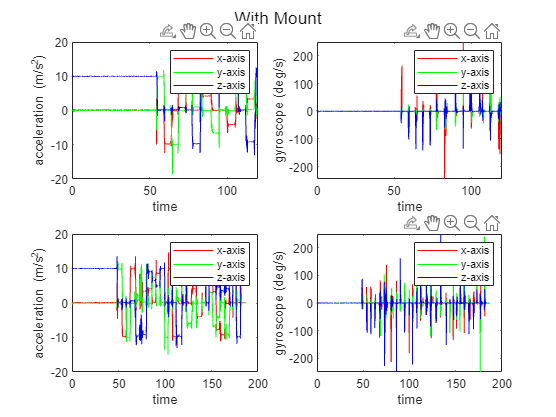

figure
subplot(2,2,3)
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,2),'r')
hold on
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,3),'g')
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,4),'b')
xlabel('time');ylabel('acceleration (m/s^2)')
legend('x-axis','y-axis','z-axis')

subplot(2,2,4)
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,5),'r')
hold on
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,6),'g')
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,7),'b')
xlabel('time');ylabel('gyroscope (deg/s)')
legend('x-axis','y-axis','z-axis')

% figure('Name','Computed Data - With Mount')
subplot(2,2,1)
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,2),'r')
hold on
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,3),'g')
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,4),'b')
xlabel('time');ylabel('acceleration (m/s^2)')
legend('x-axis','y-axis','z-axis')

subplot(2,2,2)
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,5),'r')
hold on
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,6),'g')
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,7),'b')
xlabel('time');ylabel('gyroscope (deg/s)')
legend('x-axis','y-axis','z-axis')

sgtitle('With Mount')